# Chapter 3, Section 2 (Part 1)

The goal in this activity is to introduce what is known as a subspace. Before we begin, let's make sure we understand what is meant by a "subset".

**Definition: **A set $A$ is a subset of a set $B$, written as $A\subset B$, if and only if all the elements of the set $A$ are also contained in the set $A$. For example,


$$\{1,2,3\}\subset\{0,1,2,3,4\}$$


because all of the elements of $\{1,2,3\}$ are also contained in $\{0,1,2,3,4\}$. However,


$$\{1,2,3\}\not\subset\{2,3,4,5\}$$


which means that $\{1,2,3\}$ is **not** a subset of $\{2,3,4,5\}$, because the number 1 is in the set $\{1,2,3\}$, but it is not in the set $\{2,3,4,5\}$.

**Definition: **A **subspace** $W$ of a vector space $V$ is a nonempty subset that is itself a vector space with respect to the inherited operations of vector addition and scalar multiplication in $V$. 

**Theorem:** Let $W$ be a nonempty subset of the vector space $V$. Then $W$ is a subspace of $V$ if an only if $W$ is closed under addition and scalar multiplication.

**Proof:** This is an "if and only if" theorem, so we need to prove two things:

- If $W$ is a subspace of $V$, then $W$ is closed under addition and scalar multiplication.

- If $W$ is closed under addition and scalar multiplication, then $W$ is a subspace of $V$.

**Part 1: **Assume that $W$ is a subspace of the vector space $V$. Then $W$ is nonempty and it is a vector space with respect to the inherited operations of vector addition and scalar multiplication in $V$. Since $W$ is a vector space, it must be closed under additon and scalar multiplication.

**Part 2: **Let $W$ be a nonempty subset of the vector space $V$ that is closed under addition and scalar multiplication. Therefore, it obeys the axiom laws #1 and #6. Because $W$ is a subset of the vector space $V$, all the vectors in $W$ are vectors in $V$. Hence, all the vectors in $W$ also obey the axiom laws #2, 3, 7, 8, 9, and 10. However, the axioms #4 and #5 are questionable. 

Regarding axiom #4, does $W$ contain a vector $\textbf{0}$ so that $\textbf{w}\oplus\textbf{0}=\textbf{w}=\textbf{0}\oplus\textbf{w}$ for all vectors $\textbf{w}\in W$? Let $\textbf{w}\in W$. Because we have assumed that $W$ is closed under scalar multiplication, this means that:


$$0\odot\textbf{w}\in W$$


But by Theorem 3 in our last activity (Theorem 2.1 in our textbook), $0\odot\textbf{w}=\textbf{0}$. Hence, we have proved that 


$$\textbf{0}\in W$$


Regarding axiom #5, if $\textbf{w}\in W$, then because $W$ is closed under scalar multiplication, this means that:


$$-1\odot\textbf{w}\in W$$


But by Theorem 5 in our last activity (Theorem 2.3 in our textbook), $-1\odot\textbf{w}=-\textbf{w}$. Hence, we have proved that 


$$-\textbf{w}\in W$$


Thus, all ten properties required to be a vector space are satisfied and we've proven that $W$ is a vector space, so it is a subspace of $V$.

Let's look at some examples.

# Example #1

Consider $S=\left\{\pmatrix{x\cr y}:\ xy\le0\right\}$, which is a nonempty subset of the Euclidean vector space $R^2$. Is it a subspace of $R^2$?

**Solution:** We might find a sketch helpful. If $xy\le 0$, then either $x\ge 0$ and $y\le 0$ or $x\le 0$ and $y\ge 0$. This puts us in quadrant II or quadrant IV.

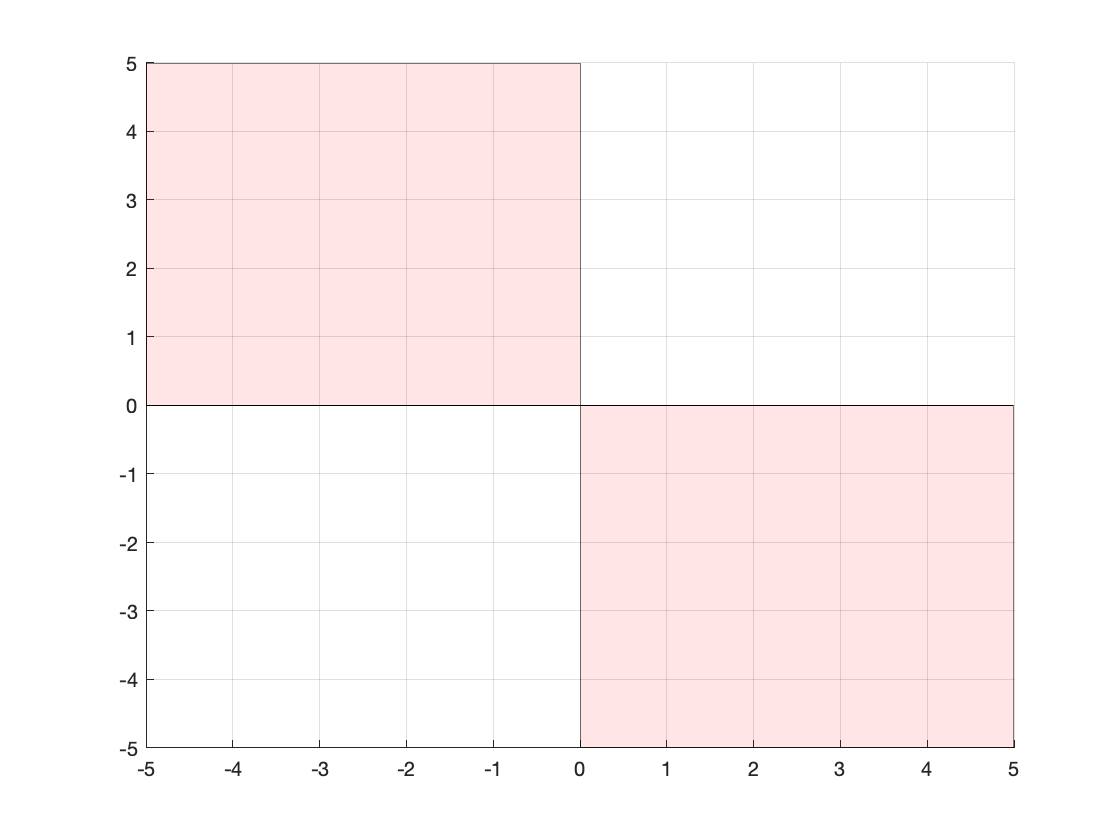

figure
patch([0 5 5 0 0],[0 0 -5 -5 0],'red','FaceAlpha',0.1)
patch([0 -5 -5 0 0],[0 0 5 5 0],'red','FaceAlpha',0.1)
grid on

It seems that this region would be closed under scalal multiplication, because any multiple of a vector in either of these regions, whether the scalar is positive or negative, will remain in this shaded region. Let's add an example to our image. We'll set $\vec u=(2,-1)^T$ and $\vec v=-2\vec u=(-4,2)^T$. Let's add these to our image.

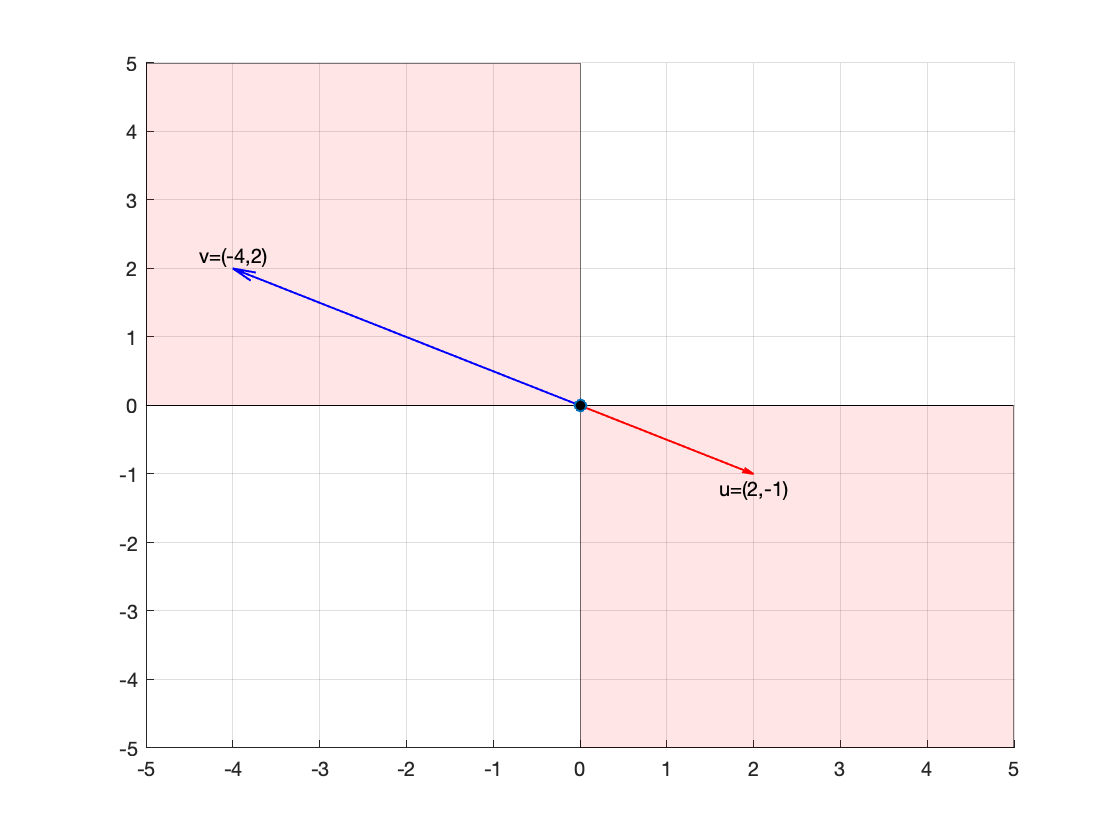

figure
patch([0 5 5 0 0],[0 0 -5 -5 0],'red','FaceAlpha',0.1)
patch([0 -5 -5 0 0],[0 0 5 5 0],'red','FaceAlpha',0.1)
hold on
quiver(0,0,2,-1,0,'LineWidth',1,'Color','r')
quiver(0,0,-4,2,0,'LineWidth',1,'Color','b')
plot(0,0,'o','MarkerFaceColor','k')
grid on
text(2,-1.2,'u=(2,-1)','HorizontalAlignment','center')
text(-4,2.2,'v=(-4,2)','HorizontalAlignment','center')
hold off

How about if we multiply by 2, using $\vec u=(2,-1)^T$ and $v=2\vec u=(4,-2)^T$.

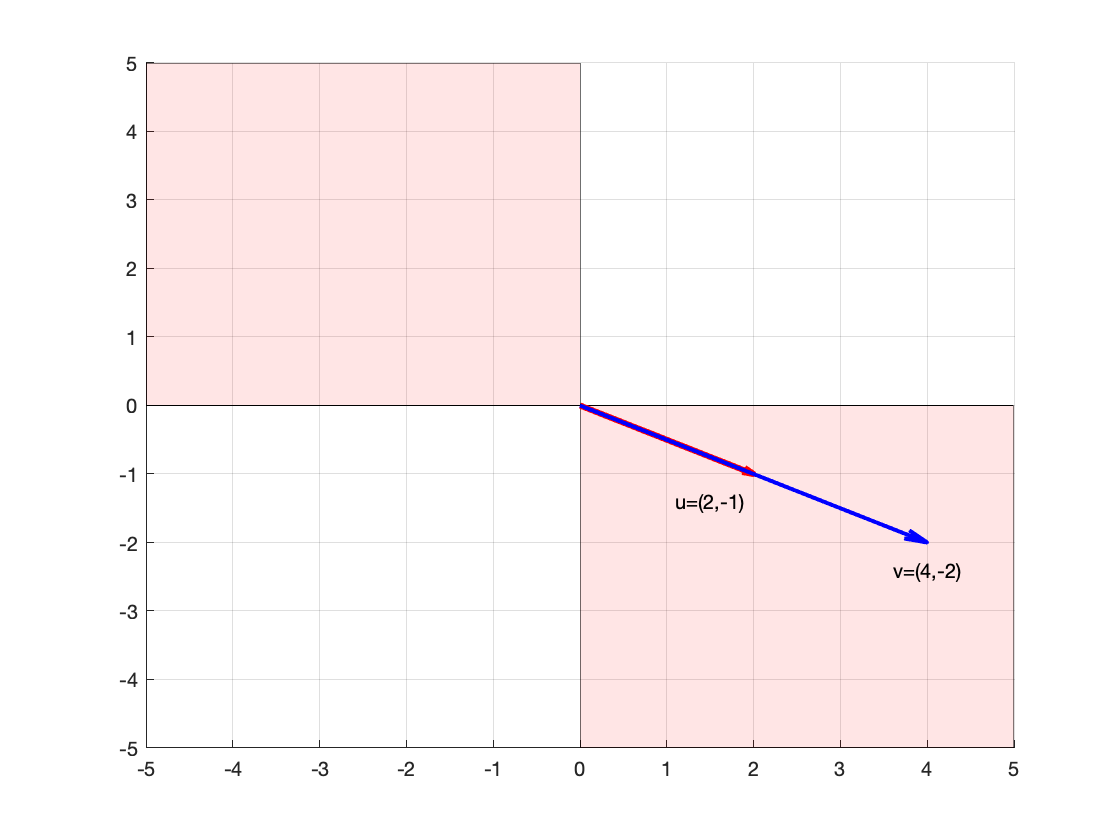

figure
patch([0 5 5 0 0],[0 0 -5 -5 0],'red','FaceAlpha',0.1)
patch([0 -5 -5 0 0],[0 0 5 5 0],'red','FaceAlpha',0.1)
hold on
quiver(0,0,2,-1,0,'LineWidth',3,'Color','r')
quiver(0,0,4,-2,0,'LineWidth',2,'Color','b')
grid on
text(1.5,-1.4,'u=(2,-1)','HorizontalAlignment','center')
text(4,-2.4,'v=(4,-2)','HorizontalAlignment','center')
hold off

Again, closed under scalar multiplication. Now, is it closed under addition? Let's try $\vec u=(2,-1)^T$ and $\vec v=(-1,3)^T$

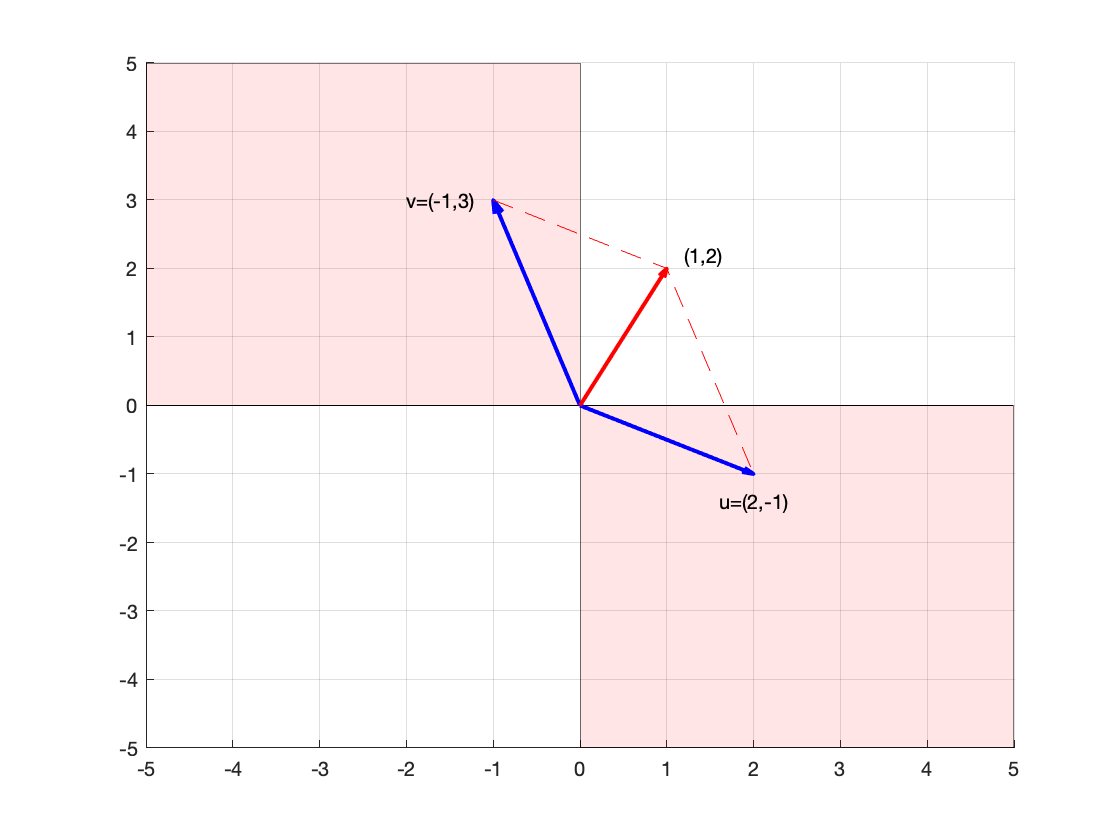

figure
patch([0 5 5 0 0],[0 0 -5 -5 0],'red','FaceAlpha',0.1)
patch([0 -5 -5 0 0],[0 0 5 5 0],'red','FaceAlpha',0.1)
hold on
quiver(0,0,2,-1,0,'LineWidth',2,'Color','b')
quiver(0,0,-1,3,0,'LineWidth',2,'Color','b')
quiver(0,0,1,2,0,'LineWidth',2,'Color','r')
grid on
text(2,-1.4,'u=(2,-1)','HorizontalAlignment','center')
text(-2,3,'v=(-1,3)')
text(1.2,2.2,'(1,2)')
line([-1 1 2],[3 2 -1],'LineStyle','--','Color','r')
hold off

The sum does not lie in the shaded region, so this subset of $R^2$ is not closed under addition and is **not** a subspace of $R^2$. 

**Alternate Approach: **We could show that this is not a subspace of $R^2$ by setting again $\vec u=(2,-1)^T$ and $\vec v=(-1,3)^T$. Note that for both vectors, $xy\ge 0$ (i.e., $(2)(-1)=-2$ and $(-1,3)=-3$). However, when we add them, we get $\vec u+\vec v=(1,2)^T$, and this time $x=1$ and $y=2$, so $xy=2$, which means the sum $(1,2)^T$ does not lie in $S=\left\{\pmatrix{x\cr y}:\ xy\le0\right\}$, so it is not closed under addition. Therefore, it is **not** a subspace of $R^2$.

# Example #2

Consider $S=\left\{\pmatrix{1+2t\cr 3-2t}:\ t\in R\right\}$, which is a nonempty subset of the Euclidean vector space $R^2$. Is it a subspace of $R^2$?

**Solution: **We have $x=1+2t$ and $y=3-2t$. Let's sketch this to see what we get.

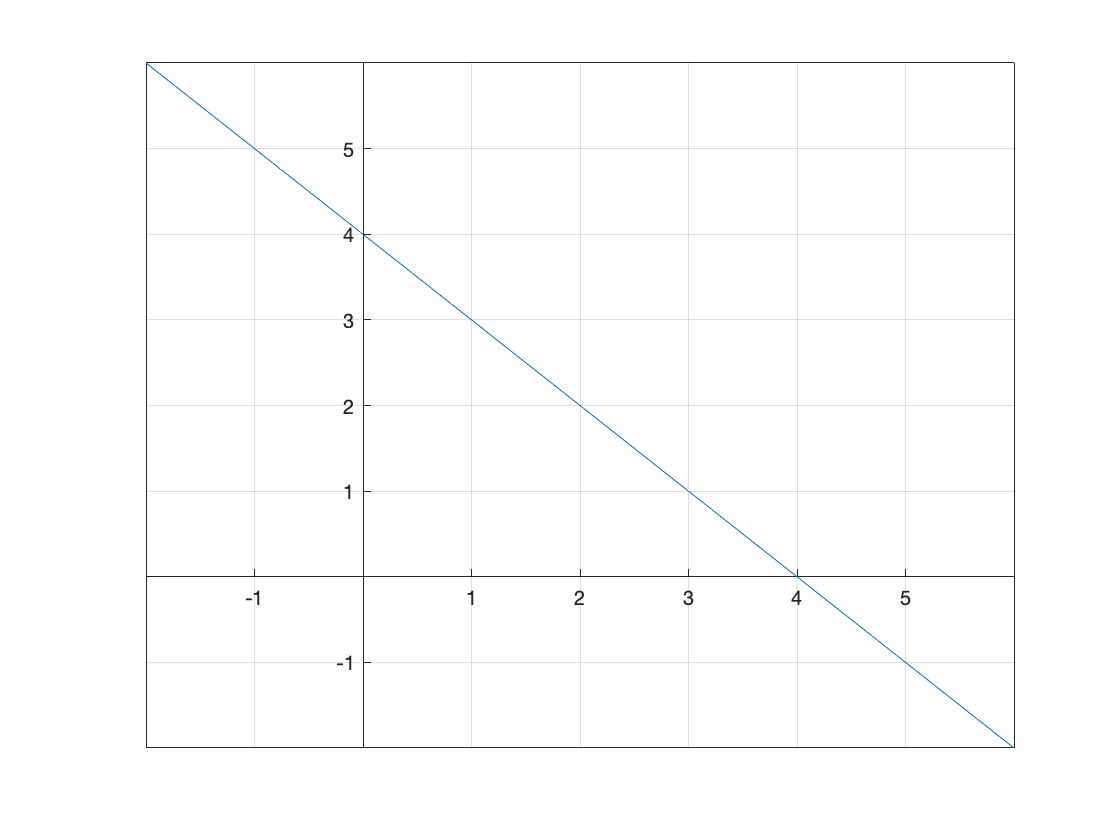

t=linspace(-3,3);
x=1+2*t; y=3-2*t;
plot(x,y)
grid on
axis([-2,6,-2,6])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

The set $S$ is a line, but it does not pass through the origin. Let's take a couple points on the line and draw vectors from the origin to our points. Using $t=0$ and $t=1$, we get the points $(1,3)$ and $(3,1)$.

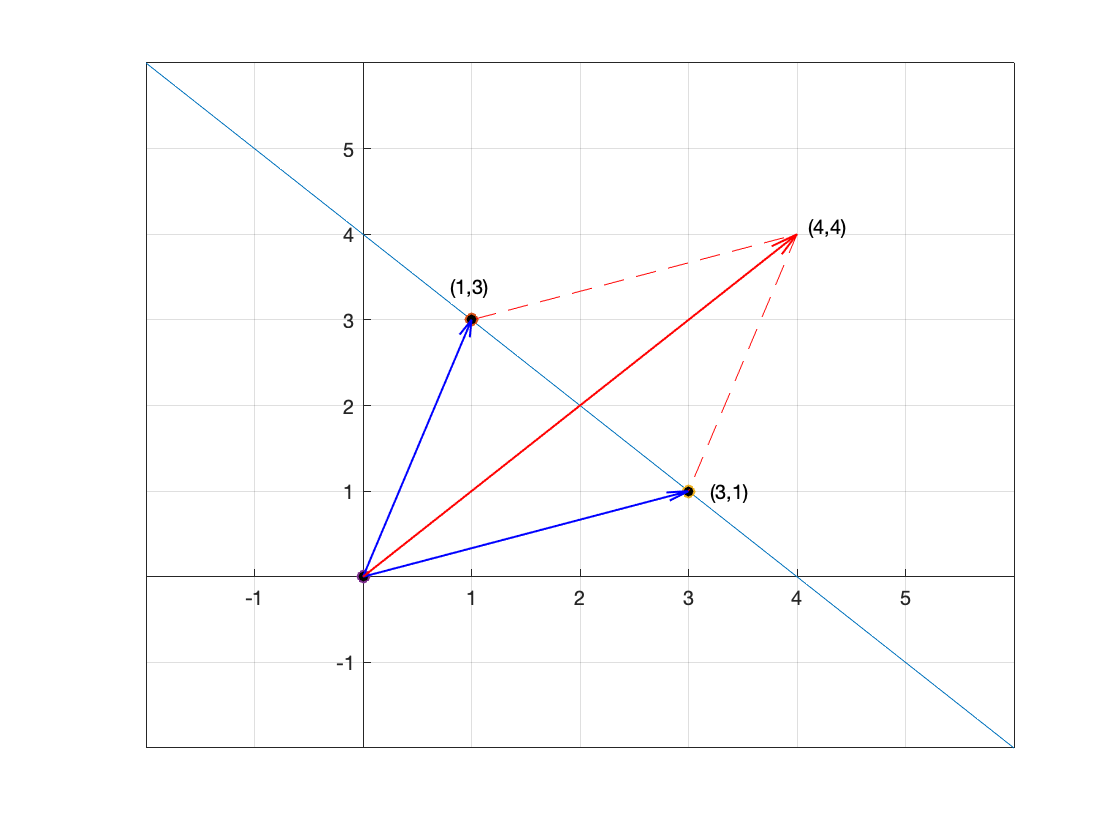

t=linspace(-3,3);
x=1+2*t; y=3-2*t;
plot(x,y)
hold on
plot(1,3,'o','MarkerFaceColor','k')
plot(3,1,'o','MarkerFaceColor','k')
plot(0,0,'o','MarkerFaceColor','k')
quiver(0,0,1,3,0,'LineWidth',1,'Color','b')
quiver(0,0,1,3,0,'LineWidth',1,'Color','b')
quiver(0,0,3,1,0,'LineWidth',1,'Color','b')
quiver(0,0,4,4,0,'LineWidth',1,'Color','r')
line([1 4 3],[3 4 1],'LineStyle','--','Color','r')
grid on
axis([-2,6,-2,6])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(0.8,3.4,'(1,3)')
text(3.2,1,'(3,1)')
text(4.1,4.1,'(4,4)')
hold off

The sum is $(4,4)$, which does not lie on the line, so $S$ is **not** closed under addition and is **not **a subspace of $R^2$.

**Alternate Approach: **We could let $t=0$ and $t=1$, which produces the points $(1,3)$ and $(3,1)$. Then, their sum is $(4,4)$. Now, how do we see (without geometry) that the point $(4,4)$ does not lie in the set $S=\left\{\pmatrix{1+2t\cr 3-2t}:\ t\in R\right\}$. Comparing


$$\pmatrix{1+2t\cr 3-2t}=\pmatrix{4\cr4}$$


we have


$$\begin{array}{rcl}
1+2t&=&4\\
3-2t&=&4
\end{array}$$


but the top equation gives us $t=3/2$ and the bottom equation gives us $t=-1/2$, so this system has no solution. Thus, $(4,4)\not\in S$, so $S$ is not closed under addition and is **not** a subspace of $R^2$.

# Example #3

Consider $S=\left\{\pmatrix{s\cr t\cr 2-s-t}:\ s, t\in R\right\}$, which is a nonempty subset of the Euclidean vector space $R^3$. Is it a subspace of $R^3$?

**Solution: ** Let's rewrite our given vector as a linear combination of vectors.


$$\begin{array}{rcl}
\pmatrix{s\cr t\cr 2-s-t}&=&\pmatrix{s\cr 0\cr -s}+\pmatrix{0\cr t\cr -t}+\pmatrix{0\cr 0\cr 2}\\
\pmatrix{s\cr t\cr 2-s-t}&=&s\pmatrix{1\cr 0\cr -1}+t\pmatrix{0\cr 1\cr -1}+\pmatrix{0\cr 0\cr 2}\\
\end{array}$$


We've see that a collection of linear combination such as


$$\pmatrix{x\cr y\cr z}=s\pmatrix{1\cr 0\cr -1}+t\pmatrix{0\cr 1\cr -1}$$


gives us a plane passing through the origin. We've added the point $(0,0,0)$ to make it clear it passes through the origin. 

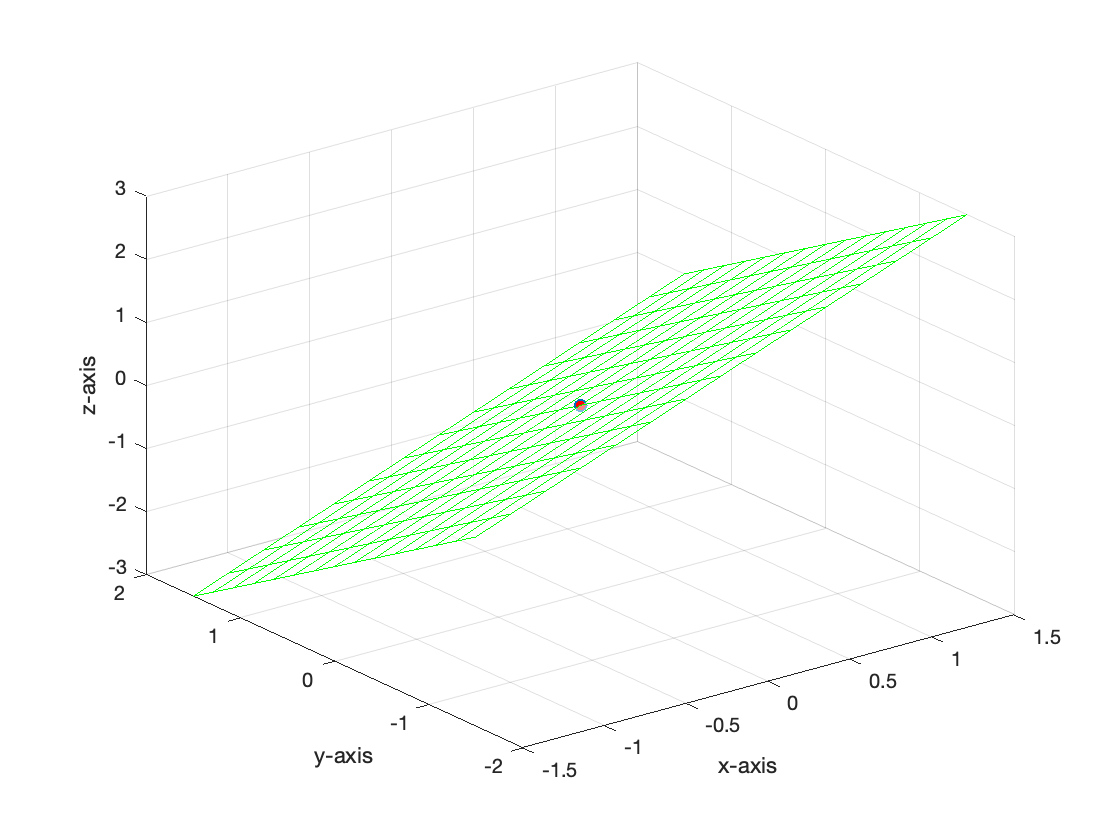

figure
s=linspace(-1.5,1.5,15);
t=linspace(-1.5,1.5,15);
[S,T]=meshgrid(s,t);
X=S;
Y=T;
Z=S-T;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.5)
hold on
plot3(0,0,0,'o','MarkerFaceColor','r')
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off

Now, the linear combination


$$\pmatrix{x\cr y\cr z}=s\pmatrix{1\cr 0\cr -1}+t\pmatrix{0\cr 1\cr -1}+\pmatrix{0\cr 0\cr 2}$$


adds 2 to the z-values, so this should shift upwards 2 units. Let's add this new plane to our image. Note that it does not pass through the origin because of the shift upward 2 units.

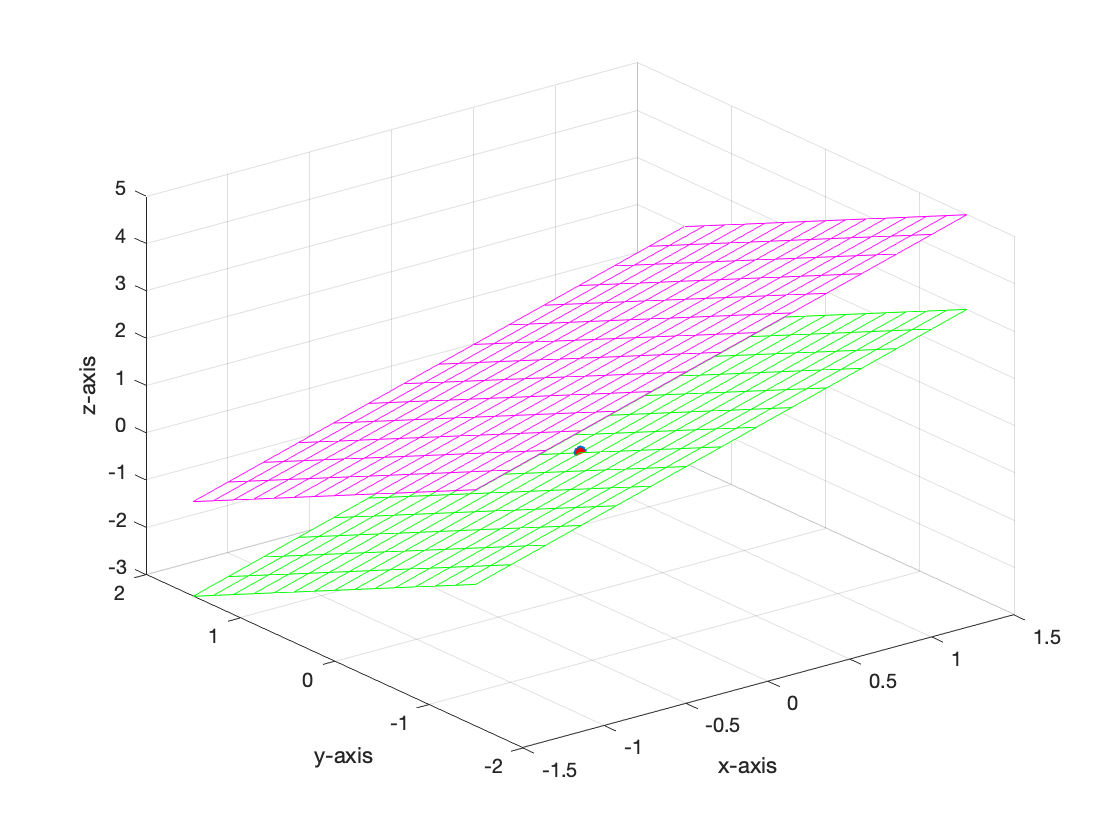

figure
s=linspace(-1.5,1.5,15);
t=linspace(-1.5,1.5,15);
[S,T]=meshgrid(s,t);
X=S;
Y=T;
Z=S-T;
mesh(X,Y,Z,'EdgeColor','g')
hold on
mesh(X,Y,Z+2,'EdgeColor','m')
plot3(0,0,0,'o','MarkerFaceColor','r')
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off

Now, is $S=\left\{\pmatrix{s\cr t\cr 2-s-t}:\ s, t\in R\right\}$ a subspace of $R^3$? Let's see if it is closed under addition by picking two points on the plane and seeing if their sum lies on the plane. For $s=-1$ and $t=0$, we get $(-1,0,3)$. For $s=1$ and $t=0$, we get $(1,0,1)$. Let's add these points to our plane and draw vectors from the origin to our points.

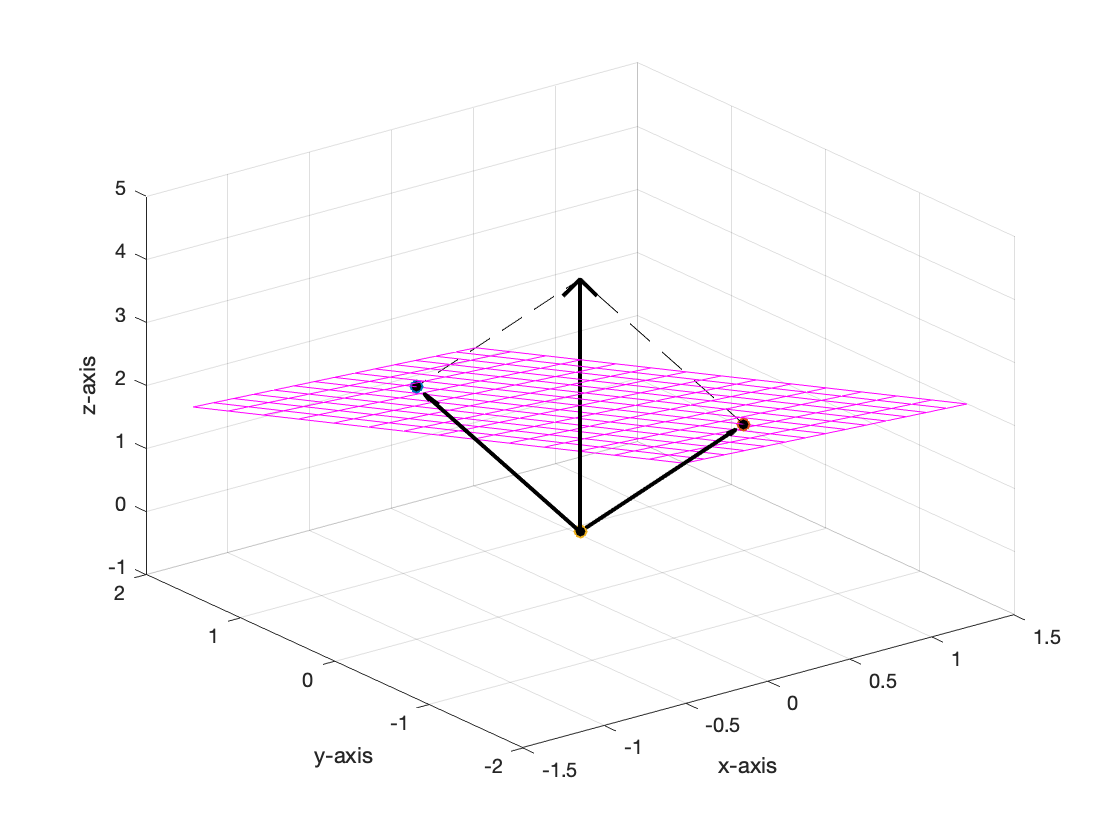

figure
s=linspace(-1.5,1.5,15);
t=linspace(-1.5,1.5,15);
[S,T]=meshgrid(s,t);
X=S;
Y=T;
Z=2-S-T;
figure
mesh(X,Y,Z,'EdgeColor','m','FaceColor','none')
hold on
plot3(-1,0,3,'o','MarkerFaceColor','k')
plot3(1,0,1,'o','MarkerFaceColor','k')
plot3(0,0,0,'o','MarkerFaceColor','k')
quiver3(0,0,0,-1,0,3,0.95,'LineWidth',2,'Color','k')
quiver3(0,0,0,1,0,1,0.95,'LineWidth',2,'Color','k')
quiver3(0,0,0,0,0,4,0,'LineWidth',2,'Color','k')
line([1 0 -1],[0 0 0],[1 4 3],'LineStyle','--','Color','k')
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off

We have clear visual evidence that the sum of the two vectors does not lie on the plane, so this space is not closed under addition and is **not** a subspace of $R^3$.

**Alternate Approach: **We could let $s=-1$ and $t=0$, which produces the point $(-1,0,3)$.  We could let $s=1$ and $t=0$, which produces the point $(1,0,1)$. Then, their sum is $(0,0,4)$. Now, how do we see (without geometry) that the point $(0,0,4)$ does not lie in the set $S=\left\{\pmatrix{s\cr t\cr 2-s-t}:\ s, t\in R\right\}$. Comparing


$$\pmatrix{s\cr t\cr 2-s-t}=\pmatrix{0\cr 0\cr4}$$


we have


$$\begin{array}{rcl}
s&=&0\\
t&=&0\\
2-s-t&=&4
\end{array}$$


but with $s=0$ and $t=0$, the bottom equation gives us $2=4$, so this system has no solution. Thus, $(0,0,4)\not\in S$, so $S$ is not closed under addition and is **not** a subspace of $R^3$.

**Important Facts: **

- Any line that passes through the origin in $R^2$ will be a subspace of $R^2$. If it does not pass through the origin, it is not a subspace of $R^2$

- Any plane that passes through the origin in $R^3$ will be a subspace of $R^3$. If it does not pass through the origin, it is not a subspace of $R^3$.